clear all;
clc;
close all;

This is a demo of OAMP for spiked matrix models with rotationally invariant noise [[2405.18081] Optimality of Approximate Message Passing Algorithms for Spiked Matrix Models with Rotationally Invariant Noise (arxiv.org)](https://arxiv.org/abs/2405.18081)

System model: $\mathbf{Y} = \frac{\theta}{N}\mathbf{x}\mathbf{x}^T + \mathbf{W}$


N = 1e6; % If the dimension is too small, we need to use some 
% empirical methods or increase the omega to enhance stability.
theta = 2;

IterNum = 10;


% Noise eigenvalue distribution
Noise_dist = "Quartic"; % "Quartic", "Sestic", "Gamma", "Beta"
gamma = 0; %parameter for quartic, gamma=1 is wigner
beta_a = 1; beta_b = 2; %parameter for Beta distribution

% "Resolvent": optimal Resolvent estimator
% "Polynomial": 
% If Noise_dist="Beta", you should use "Polynomial" denoiser
Matrix_denoiser = "Resolvent";
d_poly = 4; % Degree of polynomial estimator

PCA_init = "F";
omega0 = 0.2; %initialization, omega in [0,1]

% Signal Prior
Signal_prior = "Rad";
epsilon1 = 1/2; %parameter for sparse, 2Points and 3Points prior
epsilon2 = 1/2; %parameter for 3Points prior

%---------------------------------
param.theta = theta;
param.Noise_dist = Noise_dist;
param.Matrix_denoiser = Matrix_denoiser;
param.Signal_prior = Signal_prior;
param.IterNum = IterNum;
param.d_poly = d_poly;
param.omega0 = omega0;

**Quartic Potential**

- density: $\rho \left(x\right)=\frac{1}{2\pi \;}\left(\gamma +2a^2 \kappa +\kappa x^2 \right)\sqrt{4a^2 -x^2 }$

- where $\gamma \in \left\lbrack 0,1\right\rbrack ,\kappa =\frac{1}{27}\left(8-9\gamma +\sqrt{64-144\gamma +108\gamma^2 -27\gamma^3 }\right)$

- matrix potential: $V\left(\lambda \right)=\frac{\gamma \lambda^2 }{2}+\frac{\kappa \lambda^4 }{4}$

- hilbert transform :$H\left(\Lambda \right)=\gamma \lambda +\kappa \lambda^3$

**Pure Sestic Potential**

- density: $\rho \left(x\right)=\frac{1}{2\pi \;}\left(6a^4 \xi +2a^2 \xi x^2 +\xi x^4 \right)\sqrt{4a^2 -x^2 }$

- where $a^2 =\frac{2}{3},\xi =\frac{27}{80}$

- matrix potential: $V\left(\lambda \right)=\frac{\xi \lambda^5 }{6}$

- hilbert transform :$H\left(\Lambda \right)=\frac{1}{2\pi }\xi \lambda^5$

**Signal prior**

- Rad: $\left\lbrace +1,-1\right\rbrace$

- Sparse: $\frac{\epsilon \;}{2}\left(\delta_{\frac{1}{\sqrt{\;\epsilon \;}\;}} +\delta_{-\frac{1}{\sqrt{\;\epsilon \;}\;}} \right)+\left(1-\epsilon \;\right)\delta_0$

- 3Points: $\left(1-\frac{\alpha_1^2 }{2}-\frac{\alpha_2^2 }{2}\right)\cdot \delta_0 +\frac{\alpha_1^2 }{2}\cdot \delta_{\frac{1}{\alpha_1 }} +\frac{\alpha_2^2 }{2}\cdot \delta_{\frac{1}{\alpha_2 }}$

- 2Points: $\left(1-\alpha_1^2 \right)\cdot \delta_0 +\alpha_1^2 \cdot \delta_{\frac{1}{\alpha_1 }}$

% Define signal
kappa = 0;
xi = 0;
if Noise_dist == "Quartic"
    kappa = (8-9*gamma+sqrt(64-144*gamma+108*gamma.^2-27*gamma.^3))/27;
    if gamma == 1
        a2 = 1;
    else
        a2 = (sqrt(gamma.^2+12*kappa)-gamma)./(6*kappa);
    end
    Func_Lambda = @(y) (gamma+kappa*(2*a2+y.^2)).*sqrt(4*a2-y.^2)/(2*pi);
    HilbertT = @(lam) 1/2/pi*(gamma*lam + kappa*lam.^3);

elseif Noise_dist == "Sestic"
    xi = 27/80;
    a2 = 2/3;
    Func_Lambda = @(y) (6*a2^2*xi+(2*a2*xi)*y.^2+xi*y.^4).*sqrt(4*a2-y.^2)/(2*pi);
    HilbertT = @(lam) 1/2/pi*xi*lam.^5;
elseif Noise_dist == "Beta"
    Func_Lambda = 1; % not used
    HilbertT = 1;
else
    fprintf("Error: Input a correct eigenvalue distribution")
end

% Define function for nonlinear denosier
if Signal_prior=="Rad"
    MMSE_func = @(r,v) tanh(r);
    MMSE_func_se = @(snr) 1 - integral(@(x) normpdf(x).*tanh(snr-sqrt(snr).*x), -inf,inf ); 
elseif Signal_prior=="sparse"
    MMSE_func = @(r,snr_LE) sqrt(epsilon1).*sinh((r)./sqrt(epsilon1)).*exp(-snr_LE/(2*epsilon1))./(1-epsilon1+epsilon1.*cosh((r)./sqrt(epsilon1)).*exp(-snr_LE/(2*epsilon1)));
    aux=@(X,snr) X*integral(@(Z) normpdf(Z).*sqrt(epsilon1).*sinh((Z.*sqrt(snr)+X.*snr)./sqrt(epsilon1))*exp(-snr./(2*epsilon1))./(1-epsilon1+epsilon1*cosh((Z.*sqrt(snr)+X.*snr)./sqrt(epsilon1))*exp(-snr/(2*epsilon1))),-20,20);
    MMSE_func_se = @(snr) 1 - ( epsilon1/2*(aux(-1/sqrt(epsilon1),snr)+aux(1/sqrt(epsilon1),snr)) + (1-epsilon1)*aux(0,snr) );
elseif Signal_dist=="3Points"
    MMSE_func = @(r,snr_LE) ( epsilon1/2.*exp(-snr_LE/2/epsilon1^2 + r./epsilon1 ) + epsilon2/2.*exp(-snr_LE/2/epsilon2^2 + r./epsilon2 ) )./...
        ( 1 - epsilon1^2/2 - epsilon2^2/2 + epsilon1^2/2.*exp(-snr_LE/2/epsilon1^2 + r./epsilon1 ) + epsilon2^2/2.*exp(-snr_LE/2/epsilon2^2 + r./epsilon2 )  );
    aux1 = @(X,Z,snr) exp(-snr/2/epsilon1^2 + (Z.*sqrt(snr)+X.*snr)./epsilon1 );
    aux2 = @(X,Z,snr) exp(-snr/2/epsilon2^2 + (Z.*sqrt(snr)+X.*snr)./epsilon2 );
    aux=@(X,snr) integral(@(Z) X.*normpdf(Z).*( epsilon1/2.*aux1(X,Z,snr) + epsilon2/2.*aux2(X,Z,snr) )./( 1 - epsilon1^2/2 - epsilon2^2/2 + epsilon1^2/2.*aux1(X,Z,snr) + epsilon2^2/2.*aux2(X,Z,snr) ), -25, 25);
    MMSE_func_se = @(snr) 1 - (epsilon1^2/2.*aux(1/epsilon1,snr) + epsilon2^2/2.*aux(1/epsilon1,snr));
elseif Signal_prior=="2Points"
    MMSE_func = @(r,snr_LE) ( epsilon1.*exp(-snr_LE/2/epsilon1^2 + r./epsilon1 ) )./...
        ( 1 - epsilon1^2 + epsilon1^2.*exp(-snr_LE/2/epsilon1^2 + r./epsilon1 ) );
    aux1 = @(X,Z,snr) exp(-snr/2/epsilon1^2 + (Z.*sqrt(snr)+X.*snr)./epsilon1 );
    aux=@(X,snr) integral(@(Z) X.*normpdf(Z).*( epsilon1.*aux1(X,Z,snr) )./( 1 - epsilon1^2 + epsilon1^2.*aux1(X,Z,snr) ), -25, 25);
    MMSE_func_se = @(snr) 1 - (epsilon1^2.*aux(1/epsilon1,snr) );
end

**Optimal matrix denoiser**

Phi function:


$$\phi \left(\lambda \right)={\left\lbrack 1-\theta \pi H\left(\lambda \right)\right\rbrack }^2 +\pi^2 \theta^2 \rho^2 \left(\lambda \right)=1-\theta \cdot V^{\prime } \left(\lambda \right)+\theta^2 \cdot Q\left(\lambda \right)$$


It also equivalent to 


$$\phi \left(\lambda \right)=J\left(\lambda_1 \right)-J\left(\lambda \right)$$


where$J\left(\lambda \right)$is the preprossing function in Jean's paper.


$$\omega =\;\left\lbrack \Psi \left(\Lambda \right)\right\rbrack =1-{\left(\mathbb{E}\left\lbrack \frac{\phi \left(\Lambda \right)}{\phi \left(\Lambda \right)+\rho }\right\rbrack \right)}^{-1} \cdot \mathbb{E}\;\left\lbrack \frac{1}{\phi \left(\Lambda \right)+\rho }\right\rbrack$$


equivalently


$$\mathrm{snr}=\frac{\omega }{1-\omega }=\frac{1}{\mathbb{E}\;\left\lbrack \frac{1}{\phi \left(\Lambda \right)+\rho }\right\rbrack }-\left(\rho +1\right)$$


% algorithm function
if Noise_dist=="Quartic"
    J_Y = @(Y) gamma.*theta.*Y-kappa.*theta.^2.*Y.^2+kappa.*theta.*Y.^3;
    J_lambda1 = theta.^2.*a2*(gamma+2*a2*kappa)^2 + 1;
elseif Noise_dist=="Sestic"
    J_Y = @(Y) xi.*theta.*Y.^5-xi.*theta.^2.*Y.^4-xi.*theta.^2.*Y.^2;
    J_lambda1 = 27/50*Theta^2 + 1;
end
P_func = @(rho,Y) 1./(rho + J_lambda1 - J_Y(Y)); 

% se function
phi_func = @(lam) ( 1-theta.*pi.*HilbertT(lam) ).^2 + pi^2.*theta.^2.*Func_Lambda(lam).^2; 
Phi_snr_tmp = @(rho) integral(@(lam) Func_Lambda(lam).*phi_func(lam)./(rho+phi_func(lam)),-2*sqrt(a2),2*sqrt(a2));
Psi_func = @(rho) 1 - integral(@(lam) Func_Lambda(lam)./(rho+phi_func(lam)),-2*sqrt(a2),2*sqrt(a2))./Phi_snr_tmp(rho);


Generating eigenvalues and signal

if Noise_dist == "Beta"
    d = betarnd(beta_a,beta_b,N,1); % Generating eigenvalues 
    d = d - mean(d);
    d = d./sqrt(mean(d.^2));
else
    d = slicesample(1,N,"pdf",Func_Lambda); % Generating eigenvalues 
    d = d-mean(d);
end

% Generating signal and DFT operator
if Signal_prior == "sparse"
    x0 = sign(randn(N,1));
    x0(rand(N,1)>epsilon1) = 0;
    x0 = x0./sqrt(epsilon1);
elseif Signal_prior == "Rad"
    x0 = sign(randn(N,1));
elseif Signal_prior == "3Points"
    x0 = zeros(N,1);
    nonzeroterm = [ repmat(1/epsilon1, round(N*epsilon1^2/2),1); repmat(1/epsilon2, round(N*epsilon2^2/2),1) ];
    x0(randperm(N, length(nonzeroterm) )) = nonzeroterm;
elseif Signal_prior == "2Points"
    x0 = zeros(N,1);
    x0(randperm(N,round(N*epsilon1^2))) = 1/epsilon1;
end

We use the noise matrix $W=\textrm{Odiag}\left(\lambda \right)O^T$with$\mathrm{O}=S_1 FS_2 F^T S_3$,

where$S_1 ,S_2 ,S_3$are independent random signed diagonal matrices , and $F$is the decrete cosine transform matrix. 

We also define a P_function for algorithm, which is $\Psi \left(Y\right)\cdot f_t \left(x_{\left\lbrace t-1\right\rbrace } \right)$,

refer to equations (141)-(142) in paper.

Phase_N1 = sign(randn(N,1));
Phase_N2 = sign(randn(N,1));
Phase_N3 = sign(randn(N,1));

U_N = @(x) Phase_N3 .* dct( Phase_N2 .* idct( Phase_N1 .* x ) );
U_Nt = @(x) conj(Phase_N1) .* dct( conj(Phase_N2) .* idct( conj(Phase_N3) .* x ) );

x_tilde = U_Nt(x0);
X_D = d.*x_tilde;
X_D2 = d.*X_D;   
X_D3 = d.*X_D2;
X_D4 = d.*X_D3;
P_mean = @(rho) mean(P_func(rho,d)); 
if Noise_dist=="Quartic"
    P_mat = [ x_tilde, X_D, X_D2 ];
    QT_mat = [ gamma.*theta.^2.*x_tilde + kappa.*theta.^2.*X_D2, kappa.*theta.^2.*X_D, kappa.*theta.^2.*x_tilde]';
    P_function_d = @(x_df,rho) x_df.*P_func(rho,d) + 1/N.*bsxfun(@times, P_func(rho,d), P_mat) * ...
        ( eye(3) - 1/N.*bsxfun(@times, QT_mat, P_func(rho,d)') * P_mat)^(-1) * ...
        ( bsxfun(@times, QT_mat, P_func(rho,d)') * x_df ) - P_mean(rho).*x_df; 
elseif Noise_dist=="Sestic"
    P_mat = [x_tilde, X_D, X_D2, X_D3, X_D4];
    QT_mat = [X_D4 X_D3, X_D2, X_D, x_tilde]';
    P_function_d = @(x_df,rho) x_df.*P_func(rho,d) + xi.*Theta.^2./N.*bsxfun(@times, P_func(rho,d), P_mat) * ...
        ( eye(5) - xi.*theta.^2./N.*bsxfun(@times, QT_mat, P_func(rho,d)') * P_mat)^(-1) * ...
        ( bsxfun(@times, QT_mat, P_func(rho,d)') * x_df ) - P_mean(rho).*x_df; 
end
Y = @(x_df) theta*(x0'*x_df/N).*x0 + U_N(d.*U_Nt(x_df));
P_function = @(x_df,rho) U_N(P_function_d(U_Nt(x_df),rho));

PCA initalization

From random matrix results

if PCA_init =="T"
    [~,overlapPCA] = Max_eig(theta,Noise_dist,gamma,xi,d);
    omega0 = overlapPCA;
    fprintf("PCA results, omega = %.4f \n",omega0)
end


Testing

[rho_SE_seq,snr_opt_SE,MSE_SE,Overlap_SE]= OAMP_SE(param,MMSE_func_se,Psi_func,d);

OAMP_SE MSE:5.531747e-02, Overlap:9.446825e-01 


[MSE_sim,Overlap_sim]=OAMP(param,Y,MMSE_func,P_function,x0,rho_SE_seq,snr_opt_SE,d);

OAMP MSE:5.551540e-02, Overlap:9.444846e-01 


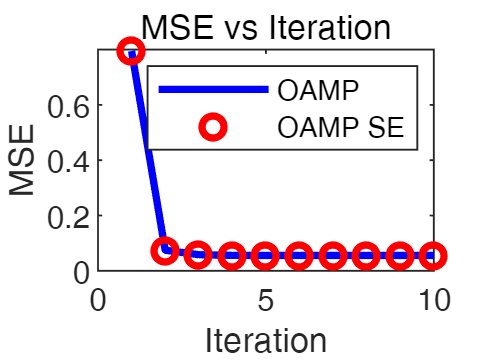



plot(1:IterNum,MSE_sim,"b-",'LineWidth',2); hold on
plot(1:IterNum,MSE_SE,"ro",'LineWidth',2);
xlabel("Iteration"); ylabel("MSE"); legend("OAMP","OAMP SE")
title("MSE vs Iteration")

State Evolution


$$\begin{array}{l}
\rho_t =\frac{1}{\textrm{dmmse}\left(\omega_{\left\lbrace t-1\right\rbrace } \right)}-1\\
\omega_t =1-{\left(\mathbb{E}\left\lbrack \frac{\phi \left(\Lambda \right)}{\phi \left(\Lambda \right)+\rho_t }\right\rbrack \right)}^{-1} \cdot \mathbb{E}\left\lbrack \frac{1}{\phi \left(\Lambda \right)+\rho_t }\right\rbrack 
\end{array}$$


function [rho_SE_seq,snr_opt_SE,MSE_SE,Overlap_SE]= OAMP_SE(param,MMSE_func_se,Psi_func,d)
Iteration = param.IterNum;
omega0 = param.omega0;
Matrix_denoiser = param.Matrix_denoiser;
d_poly = param.d_poly;
theta = param.theta;

snr_LE_SE = omega0/(1-omega0);
for it = 1:Iteration
        
    % MMSE function
    MMSE_SE = MMSE_func_se(snr_LE_SE);
    MSE_SE(it) = real(MMSE_SE);
    Overlap_SE(it) = abs(1 - real(MMSE_SE));

    dmmse_SE = 1/( 1/MMSE_SE - snr_LE_SE);
    rho_SE = 1/(dmmse_SE) - 1;
    
    % Matrix denoiser
    if Matrix_denoiser == "Resolvent"
        omega = Psi_func(rho_SE);
        snr_LE_SE = omega/(1-omega);
    elseif Matrix_denoiser == "Polynomial"
        [~,snr_LE_SE] = Poly_se(d,theta,1/rho_SE,d_poly); 
    else
        fprintf("Please choose a Matrix denoise\n")
        return
    end
         
    rho_SE_seq(it) = rho_SE;
    snr_opt_SE(it) = snr_LE_SE;
     
end


fprintf("OAMP_SE MSE:%e, Overlap:%e \n",MSE_SE(it),Overlap_SE(it))
end

Algorithm

function [MSE_sim,Overlap_sim]=OAMP(param,Y,MMSE_func,P_function,x0,rho_SE_seq,snr_opt_SE,d)
Iteration = param.IterNum;
omega0 = param.omega0;
Matrix_denoiser = param.Matrix_denoiser;
d_poly = param.d_poly;
theta = param.theta;

N = length(x0);
alpha_sim = sqrt(omega0);
sigma2_sim = 1-omega0;
r_hat = alpha_sim.*x0 + sqrt(sigma2_sim).*randn(N,1);
for it = 1:Iteration

    % MMSE function
    x_hat_post = MMSE_func(r_hat * alpha_sim/sigma2_sim,alpha_sim^2/sigma2_sim);
    div = ( 1 - mean(x_hat_post.^2) ) * alpha_sim/sigma2_sim;
    
    x_hat = x_hat_post - div * r_hat;
    
    %Empirical way to calculate rho
%     Var = 1 - mean(x_hat_post.^2);
%     dmmse = 1/( 1/mean(Var) - alpha_sim^2/sigma2 );
%     rho = 1/dmmse-1;
    
    rho = rho_SE_seq(it);

%       Note that in this place we use the result from se to deteremine the
%       parameter v. however, if the system dimension is low, this
%       parameter is inaccuracy, at this time we should compute the maximum
%       eigenvalue of the real data matrix and compute the sutible rho.
    
    if Matrix_denoiser == "Resolvent"
        r_hat = P_function(x_hat,rho);   
        snr = snr_opt_SE(it);
    elseif Matrix_denoiser == "Polynomial"
        % calculate snr and optimal combining parameter by state evolution
        [Alpha,snr] = Poly_se(d,theta,1/rho,d_poly);
        
        R = zeros(N,d_poly);
        mean_d = zeros(d_poly,1);
        R(:,1) = Y(x_hat);
        mean_d(1) = mean(d);
        for ii = 2:d_poly
            R(:,ii) = Y(R(:,ii-1));
            mean_d(ii) = mean(d.^ii);
        end
        R = R - x_hat*mean_d';
        % optimal combining
        r_hat = R*Alpha;
    else
        fprintf("Please choose a Matrix denoise\n")
        return
    end
         


    % scaling
%         alpha = r_hat'*x/norm(x)^2;
%         r_hat = r_hat/alpha;
%         alpha = 1;
%         % measure
%         alpha_sim =  r_hat'*x/norm(x)^2;
%         sigma2_sim = norm(r_hat - alpha_sim * x)^2/norm(x)^2;      

    r_hat = r_hat/(norm(r_hat)/sqrt(N))*sqrt(1+1/snr);
    alpha_sim = 1;
    sigma2_sim = 1/snr_opt_SE(it);
    

    MSE_sim(it) = norm(x_hat_post-x0)^2/N;
    Overlap_sim(it) = (x_hat_post'*x0)^2/norm(x_hat_post)^2/norm(x0)^2;

end

fprintf("OAMP MSE:%e, Overlap:%e \n",MSE_sim(it),Overlap_sim(it))
end


PCA random matrix results

% Bisection, find maximum eigenvalue
function [max_eig_cal,overlap_cal] = Max_eig(Lambda,Eig_dist,gamma,xi,d)
    
    if Eig_dist == "Quartic"
        kappa = (8-9*gamma+sqrt(64-144*gamma+108*gamma.^2-27*gamma.^3))/27;
        if gamma == 1
            a2 = 1;
        else
            a2 = (sqrt(gamma.^2+12*kappa)-gamma)./(6*kappa);
        end
        sjt = @(z) 1/2*(gamma*z+ kappa*z.^3 - ( gamma + 2*a2*kappa + kappa*z.^2 ).*sqrt(z.^2-4*a2));
        sjt_diff = @(z) 1/2*( gamma + 3*kappa*z.^2 - 2*kappa*z.*sqrt(z.^2-4*a2) - ...
            z.*( gamma + 2*a2*kappa + kappa*z.^2 )./sqrt(z.^2-4*a2) );

    elseif Eig_dist=="Sestic"
        a2 = 2/3;
        sjt = @(z) 1/2*(xi*z.^5 - ( 6*a2^2*xi + 2*a2*xi*z.^2 + xi*z.^4 ).*sqrt(z.^2-4*a2));
        sjt_diff = @(z) 1/2*( 5*xi*z.^4 - (4*a2*xi*z+4*xi*z.^3).*sqrt(z.^2-4*a2) - ...
            1/2*( 6*a2^2*xi+2*a2*xi*z.^2+xi*z.^4 ).*(4*z.^3)./sqrt(z.^2-4*a2) );
    else
        % some empirical method
        a2 = max(d./2)^2;
        sjt = @(z) mean(1./(z-d));
        sjt_diff = @(z) mean(-1./(z-d).^2);
    end
    
    %bisection
    itnum = 1000;
    if Lambda < real(1/sjt(2*sqrt(a2)))
        max_eig_cal = 2*sqrt(a2);
        overlap_cal = 0;
    else

        x_1 = 0;
        x_2 = 10*Lambda;
        it = 1;
        while it < itnum
            
            max_eig = (x_2 + x_1)/2;
            Lambda_tmp = 1/sjt(max_eig);
            if Lambda_tmp > Lambda
                x_2 = max_eig;
            else
                x_1 = max_eig;
            end
            it = it + 1;
            if abs(x_2-x_1) < 1e-6
                break
            end
        end
        max_eig_cal = (x_1+x_2)/2; 
        overlap_cal = -1/Lambda^2/sjt_diff(max_eig_cal);
    end

end

State evolution of Polynomial method

The output of the $k$-th order polynomial estimator is 


$$\overline{Y^k} \eta_{df} \approx \beta_k \cdot x_0 + n_k,  \quad \eta_{df}=x_0 + \sigma\cdot z$$
 

where 


$$\beta_k \approx \sum_{i=0}^{k-1} \alpha_{k-i} m_i
\quad
\alpha_{0} = 1, \quad \alpha_{k} =\theta\cdot\sum_{i=0}^{k-1} \alpha_{k-1-i} m_{i} $$


and the covariance $\langle n_k ,n_l \rangle$


$$\frac{1}{N} \langle n_k, n_l \rangle   
=
\sum_{i=1}^{k}\sum_{j=1}^{\ell} \alpha_{k-i}\alpha_{\ell-j} (m_{i+j}-m_i m_j) + (m_{k+\ell} - m_k m_\ell)\sigma^2.$$


function [Alpha,snr] = Poly_se(d,theta,sigma2,d_poly)

% This function compute the optimal combing of polynomial estimator
% and output snr and the combining coefficient
% d is the eigenvalues of observation matrix
% Lambda is the system snr
% sigma2 is the input snr
% K is the order of polynomial

% compute the moment sequent, note that m(1) = m_0 = 1
m = zeros(2*d_poly+1,1);
m(1) = 1;
for k = 1:2*d_poly
    m(k+1) = mean(d.^k);
end
% compute the alpha, note that alpha(1) = alpha_0 = 1
alpha = zeros(d_poly+1,1);
alpha(1) = 1;
for k = 1:d_poly
    
    alpha_k = 0;
    for i=1:k
        alpha_k = alpha_k + alpha(k+1-i)*m(i);
    end
    alpha(k+1) = theta*alpha_k;

end

% compute the covariance matrix
cov = zeros(d_poly);
for k = 1:d_poly
    for l = 1:d_poly
        cov_kl = 0;
        for i = 1:k
            for j = 1:l
                cov_kl = cov_kl + alpha(k+1-i)*alpha(l+1-j)*(m(i+j+1)-m(i+1)*m(j+1));
            end
        end
        cov_kl = cov_kl + (m(k+l+1)-m(k+1)*m(l+1))*sigma2;
        cov(k,l) = cov_kl;
    end
end

% compute beta
beta = zeros(d_poly,1);
for k = 1:d_poly
    beta_k = 0;
    for i = 1:k
        beta_k = beta_k + alpha(i+1)*m(k+1-i);
    end
    beta(k) = beta_k;
end

snr = beta'*cov^-1*beta;
Alpha = cov^-1*beta./snr;

end
